## L6: Analiza mowy w dziedzinie czasu

Proszę zaimplementować brakujące funkcje (label, pitchwin) tak, aby ostatecznie uzyskać segmentację sygnału na ciszę, fragmenty dźwięczne i bezdźwięczne. Wszystkie funkcje proszę zaimplementować na końcu dostarczonego notatnika

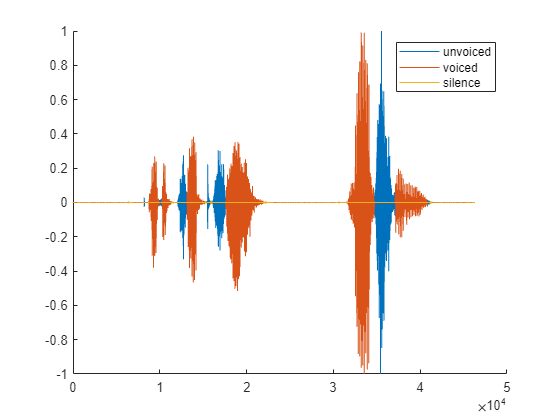

[x, fs] = audioread("percepcja.wav");
x = x / max(x);

lbls = label(x, fs);
f0 = pitchwin(x, fs, round(fs * 0.1));
f0(lbls ~= 2) = 0;

silence = x;
silence(lbls ~= 0) = 0;

unvoiced = x;
unvoiced(lbls ~= 1) = 0;

voiced = x;
voiced(lbls ~= 2) = 0;

figure;
hold on;
plot(unvoiced);
plot(voiced);
plot(silence);
ylim([-1, 1]);
legend("unvoiced", "voiced", "silence");

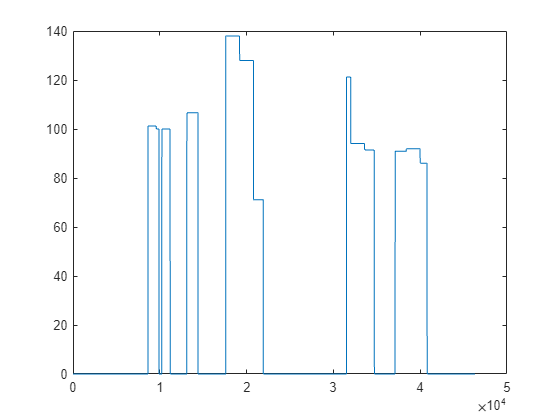


figure;
plot(f0);

function [lbls] = label(x, fs)
% autor : Tomasz Pawlak
% cel : szufladkowanie ramek sygnału na dźwięczne głoski, niedźwięczne
% głoski oraz szum
%
% x = sygnał spróbkowany częstotliwością fs
%
% inicjacja stałych przydatnych przy analizie podziału głosek
NOT_NOISED_MEAN = 0.05;
STR_THRESHOLD = 0.01;
STE_THRESHOLD = 0.05;
SOUNDNESS_THRESHOLD = 0.2;
% długość okna analizy: 160 klatek
win_len = round(fs * 0.01);

% inicjacja lbls
lbls = -1*ones(length(x),1);

% obliczanie funkcji stosunku sygnał/szum dla sygnału x
ste = conv(x.^2, ones(1,win_len), 'same');
ste = ste / max(ste);
str = sqrt(ste);

% odrzucenie próbek niedźwięcznych - nie chcielibyśmy ich analizować
lbls_active = 1 * (str > STR_THRESHOLD);

% iteracja po ramkach - ostatnia jest ucięta do swojego realnego końca
for i=1:ceil(length(x)/win_len)
    if i*win_len > length(x)
        endpoint = length(x);
    else
        endpoint = i*win_len;
    end

    win = x(win_len*(i-1)+1:endpoint);

    % średnie sound to noise ratio ramki aby poddawać ją analizie
    if mean(lbls_active(win_len*(i-1)+1: endpoint)) > NOT_NOISED_MEAN
        % współczynnik przychodzenia przez zero określa odróżnienie głosek
        % dźwięcznych od bezdźwięcznych
        zcr = zerocrossrate(win);

        % empirycznie ustalony próg dźwięczności celem odróżnienia głosek
        if zcr > SOUNDNESS_THRESHOLD
            lbls(win_len*(i-1)+1: endpoint) = 1;
        else
            lbls(win_len*(i-1)+1: endpoint) = 2;
        end
    else
        lbls(win_len*(i-1)+1: endpoint) = 0;
    end

end
end

function [x_p] = pitchwin(x, fs, win_len)
% autor : Tomasz Pawlak
% cel : wyznaczenie częstotliwości f0 dla ramek próbkowanego sygnału BEZ
% pominięcia głosek bezdźwięcznych oraz ciszy
% schemat działania : 
%   > ramka bez dzwieku -> przypisz "0" 
%   > ramka z dzwiekiem -> przypisz f0 = fs/N;
%   N - indeks ramki gdzie autokorelacja ma największą wartość
% parametry wejściowe :
%   syngał x próbkowany z częstotliwością fs podzielony na ramki o długości
%   win_len (zakładając że ostatnia może być krótsza)

x_p = zeros(length(x),1);

% inicjacja największej dopuszczalnej f0 głosu ludzkiego
f_max = 300;
% inicjacja minimalnego błędu
lag_min = fs / f_max;

% iteracja po ramkach - ostatnia jest ucięta do swojego realnego końca
for i=1:ceil(length(x)/win_len)
    if i*win_len > length(x)
        endpoint = length(x);
    else
        endpoint = i*win_len;
    end
    % ograniczenie sygnału badanego do ramki
    win = x(win_len*(i-1)+1:endpoint);
    % autokorelacja sygnału
    [c, lags] = xcorr(win, "normalized");
    % przycięcie sygnału autokorelowanego i jego indeksów w oknie do
    % wartości spełniających założenia minimalnego odchylenia
    c = c(lags > lag_min);
    lags = lags(lags > lag_min);
    % znalezienie maksymów lokalnych sygnału z założeniem szerokości oraz
    % znaczenia (prominence)
    [pks, loc] = findpeaks(c, "MinPeakProminence", 0.2, "MinPeakWidth", 3);
    % znalezienie maksymum globalnego
    max_peak = maxk(pks, 1);
    % inicjacja indeksu, żeby błędami nie sypał
    ind = -1;
    if ~isempty(max_peak)
        % znalezienie indeksu peaku w oknie o najwyższym sygnale
        ind = find(pks==max_peak);
    end
    if ind ~= -1
        % przypisanie odwrotności wartości szczytu o najwyższym sygnale -
        % wymnożone przez częstotliwość próbkowania
        x_p(win_len*(i-1)+1:endpoint) = fs/lags(loc(ind));
    end
end
end

function zcr = zerocrossrate(x)
    zc = diff(sign(x));
    zcr = sum(zc ~= 0) / length(x);
end